clear
load data5.mat
n=length(data.CzasLokalnyUTC0100)

n = 6960

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   15.09.2025 12:00:00
   15.09.2025 12:01:00
   15.09.2025 12:02:00
   15.09.2025 12:03:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   20.09.2025 07:56:00
   20.09.2025 07:57:00
   20.09.2025 07:58:00
   20.09.2025 07:59:00


We observe fs of 60s

From time vector:

T=60; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;



TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;


X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

t=T*(1:n);
size(X)

ans =            4        6960


[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

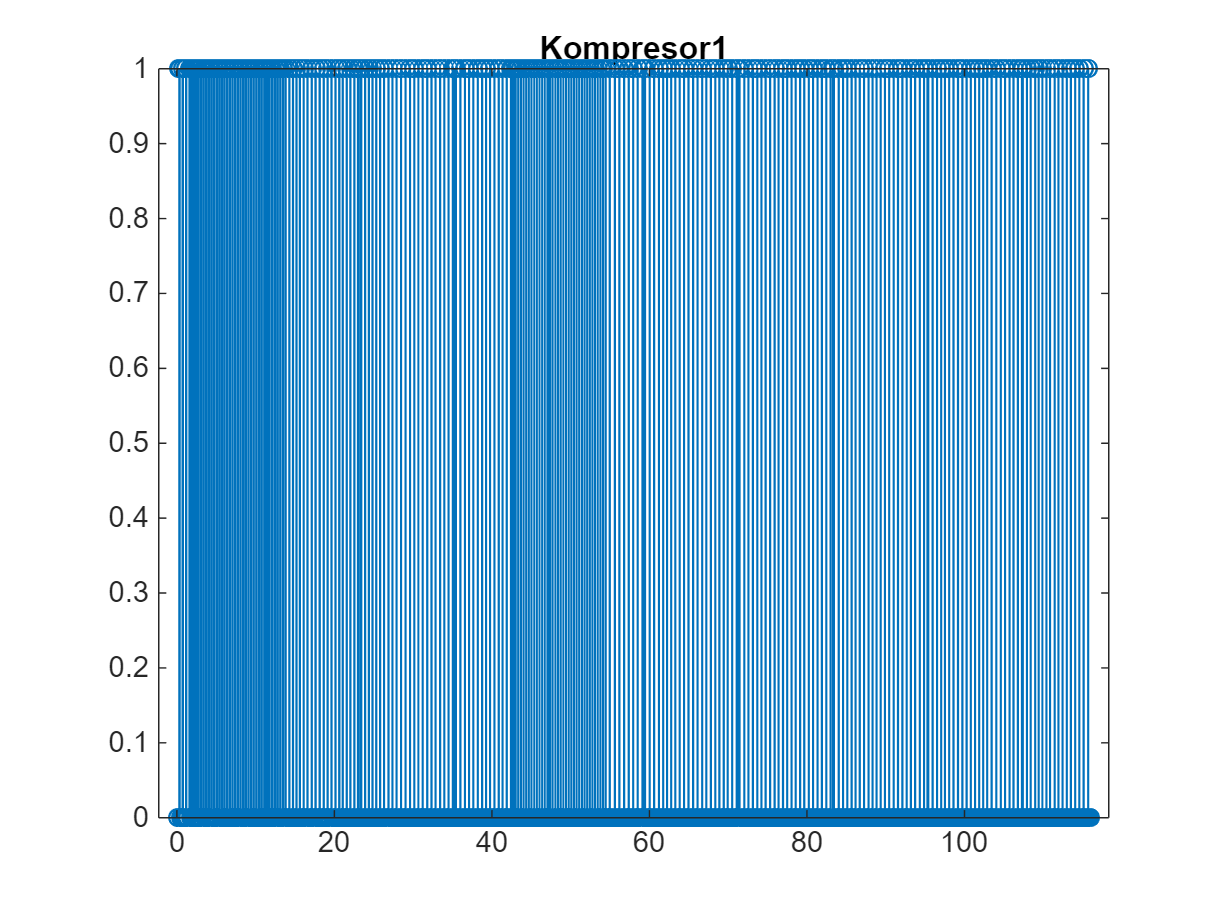

stem(t./(60*60),X(1,:))
title('Kompresor1')

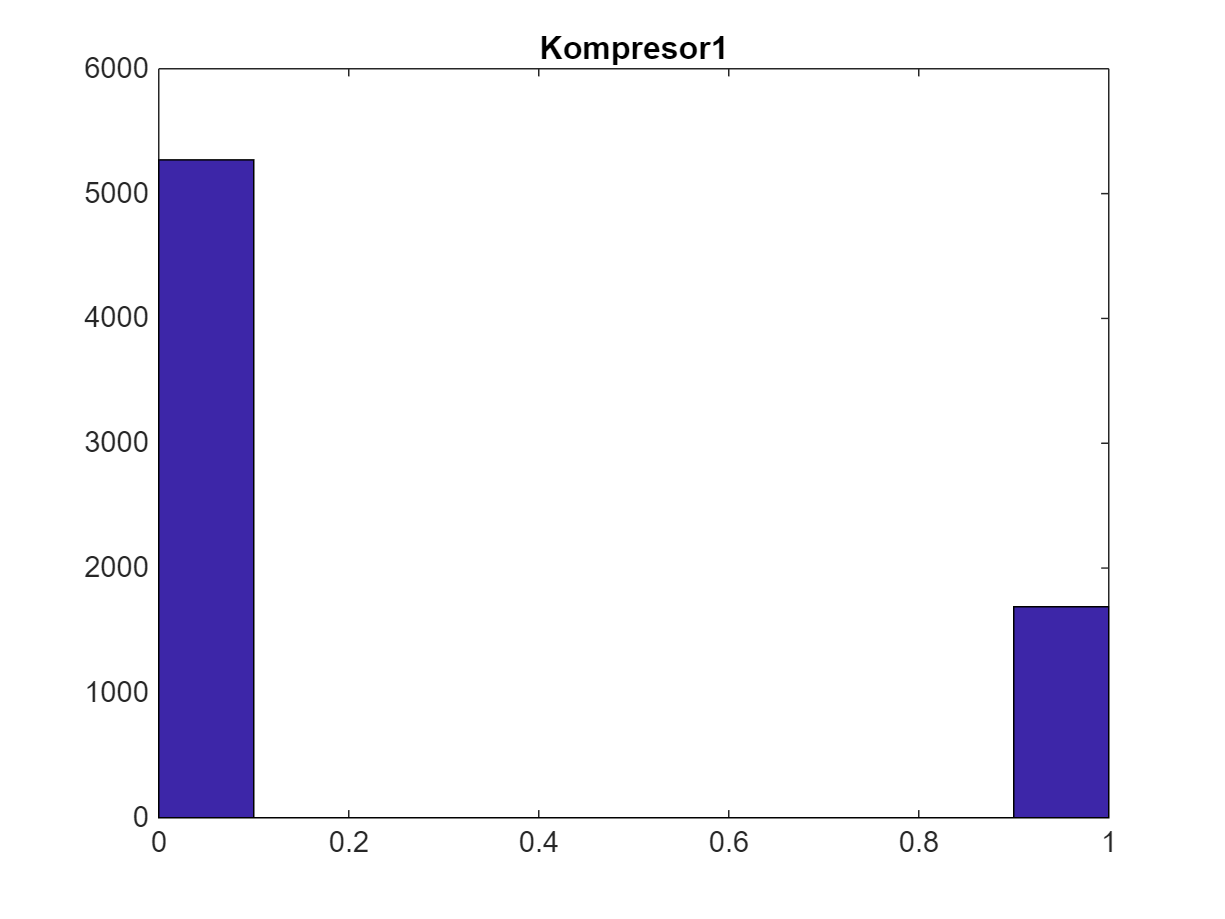

hist(X(1,:))
title('Kompresor1')

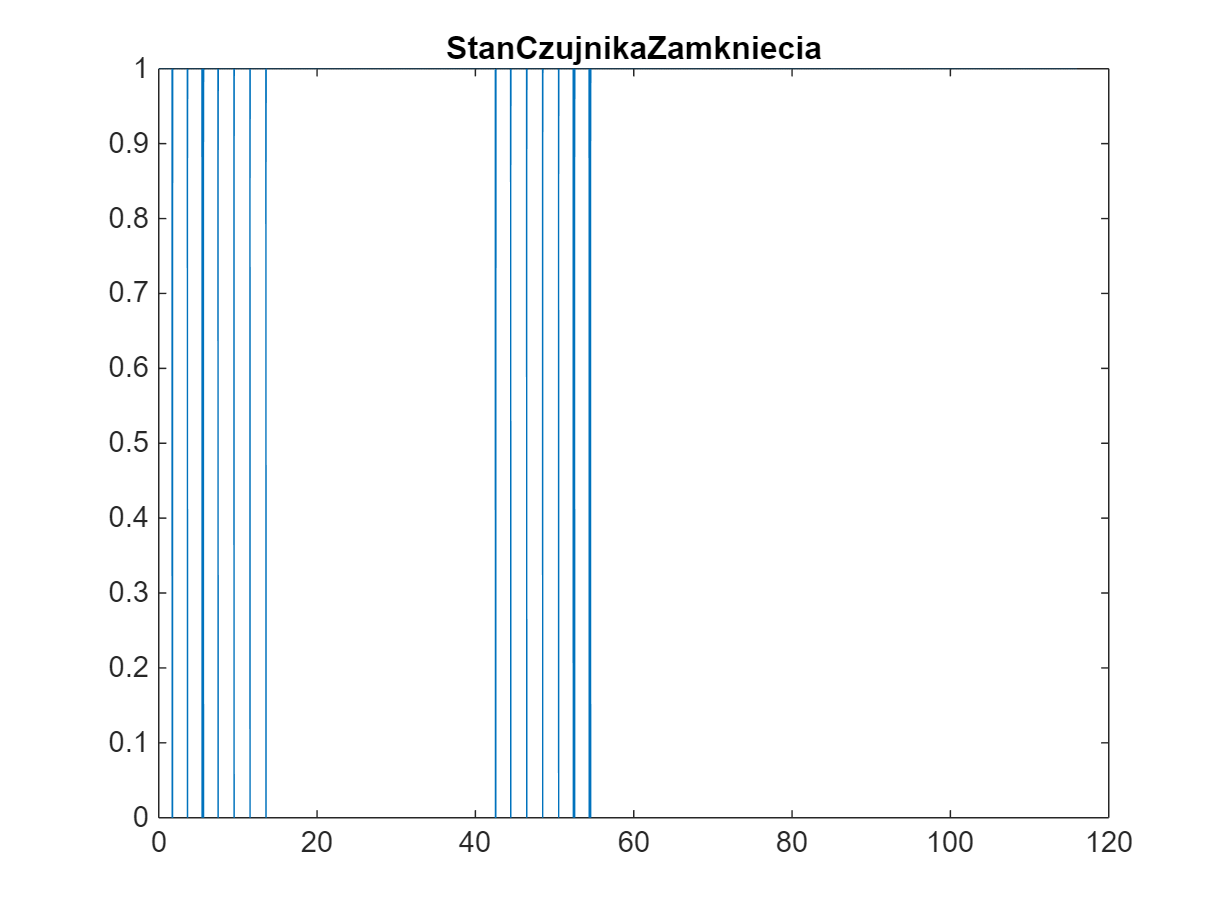

plot(t/(60*60),X(2,:))
title('StanCzujnikaZamkniecia')

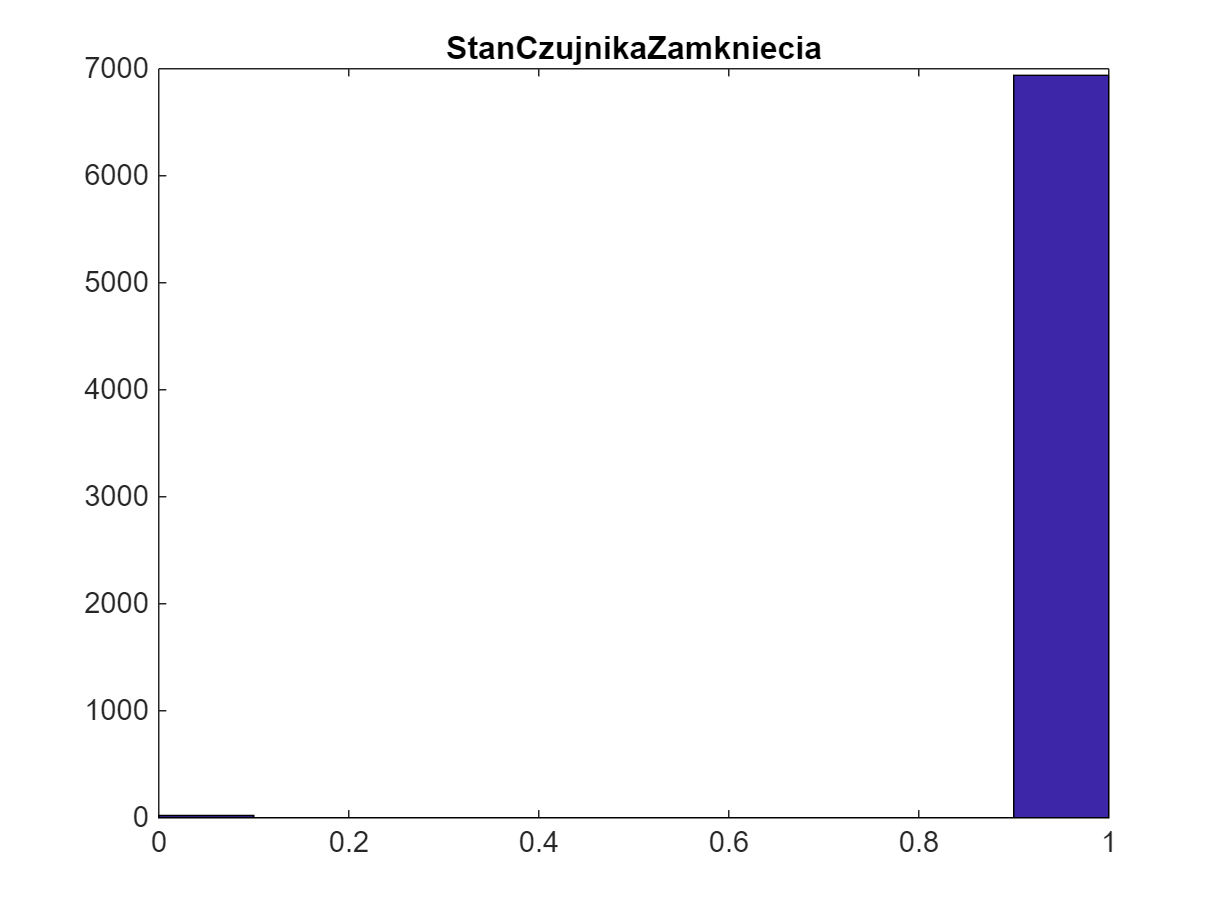

hist(X(2,:))
title('StanCzujnikaZamkniecia')

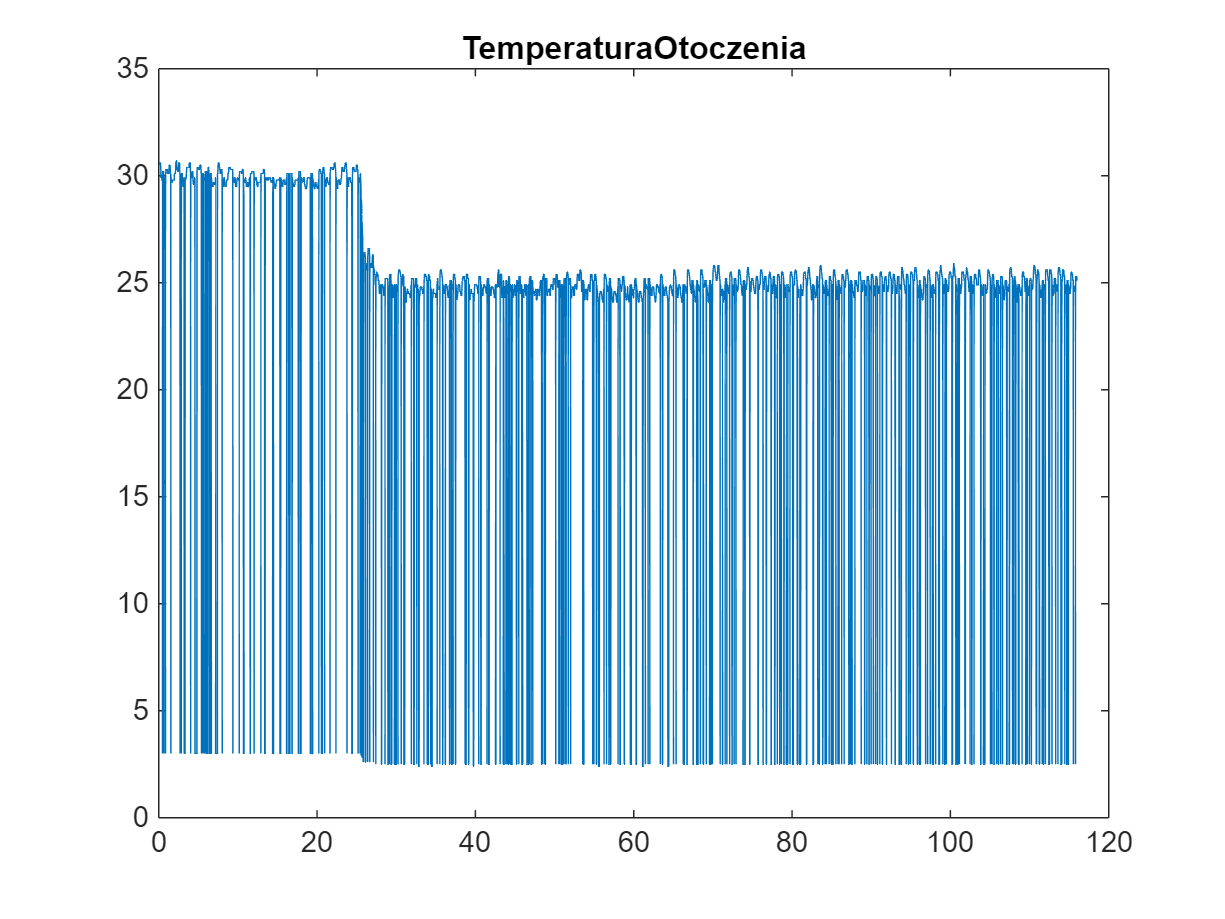

plot(t/(60*60),X(3,:))
title('TemperaturaOtoczenia')

We see measurement errors. We need to delete and interpolate values between 2 and 3.5 degrees

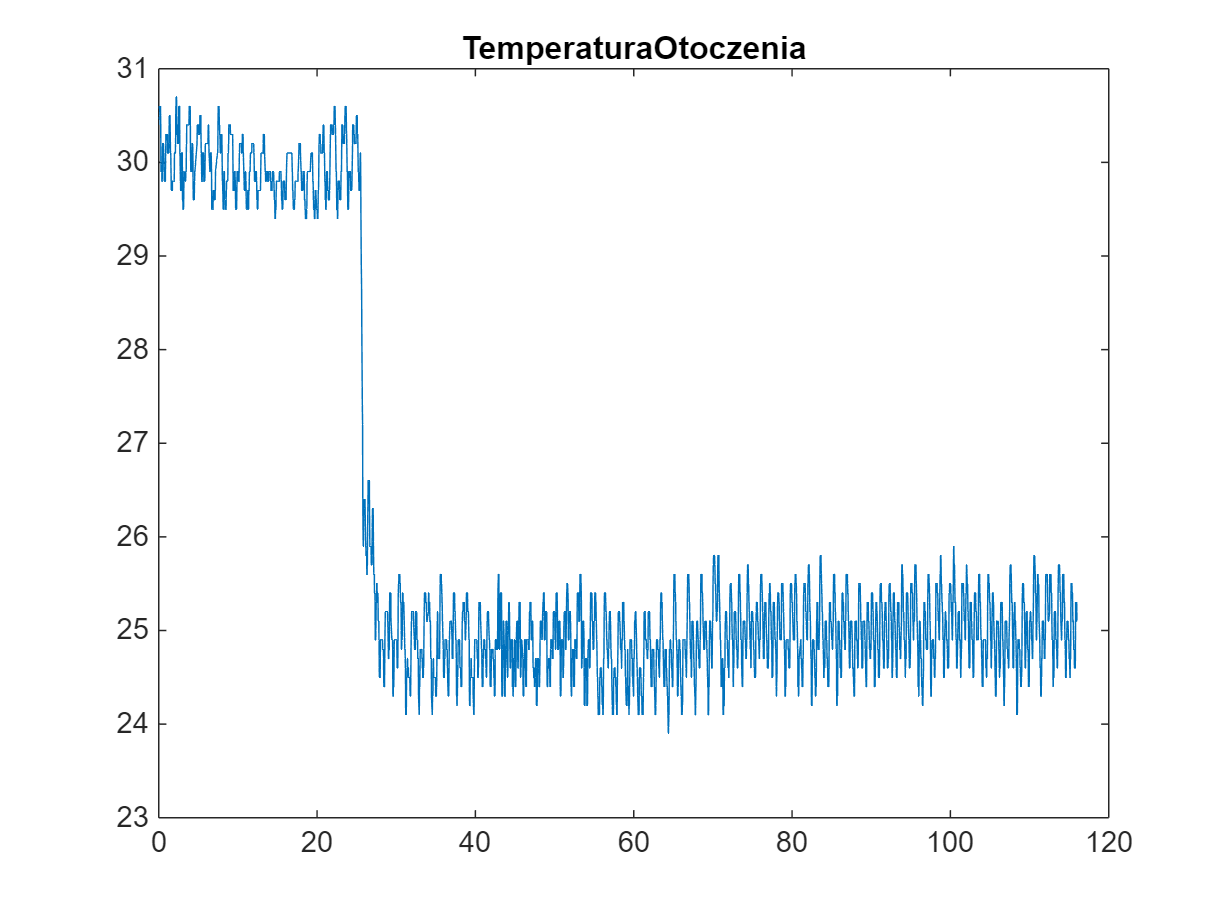

plot(t/(60*60),InterpolateData(X(3,:),[2,3.5],t_all))
title('TemperaturaOtoczenia')

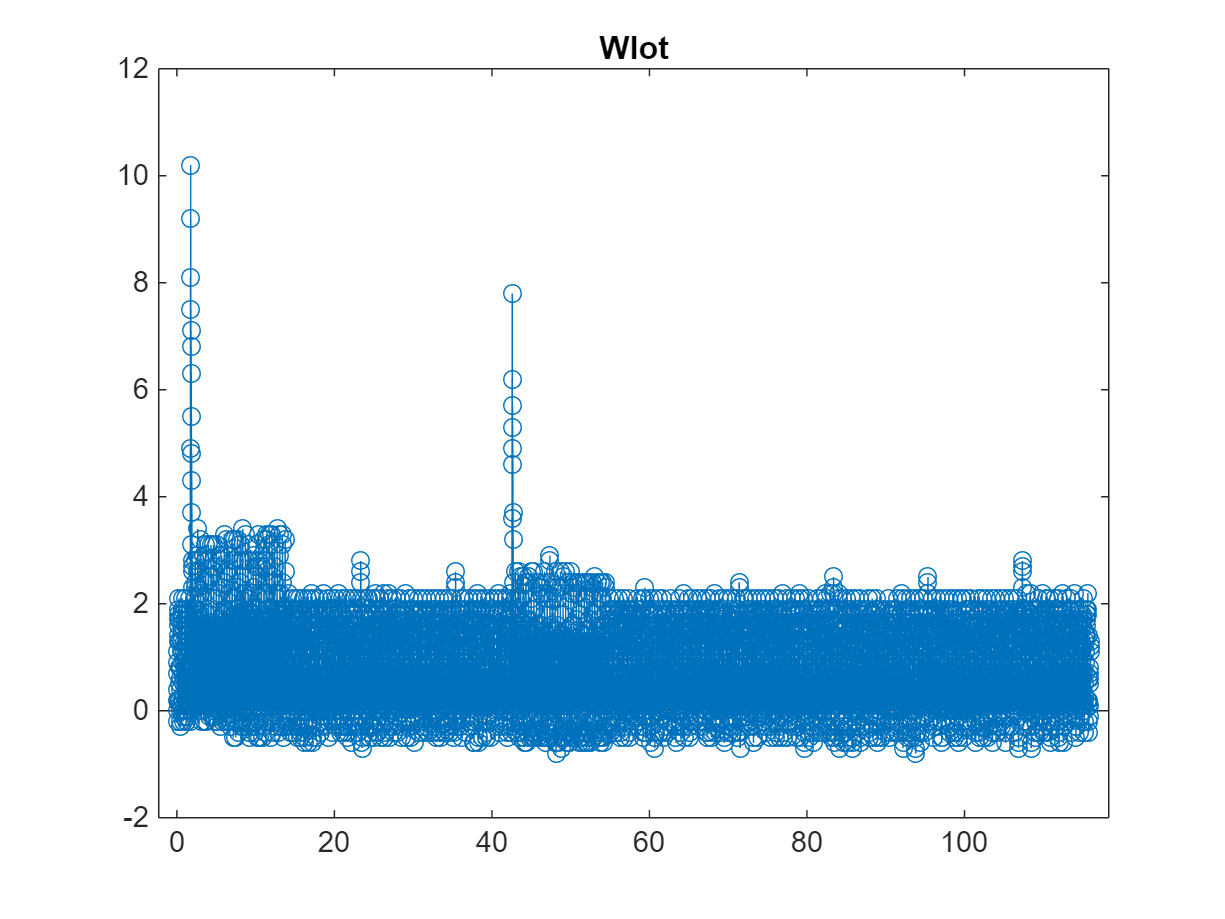

stem(t/(60*60),X(4,:))
title('Wlot')

errors between 0.05 and 0.15 degrees C

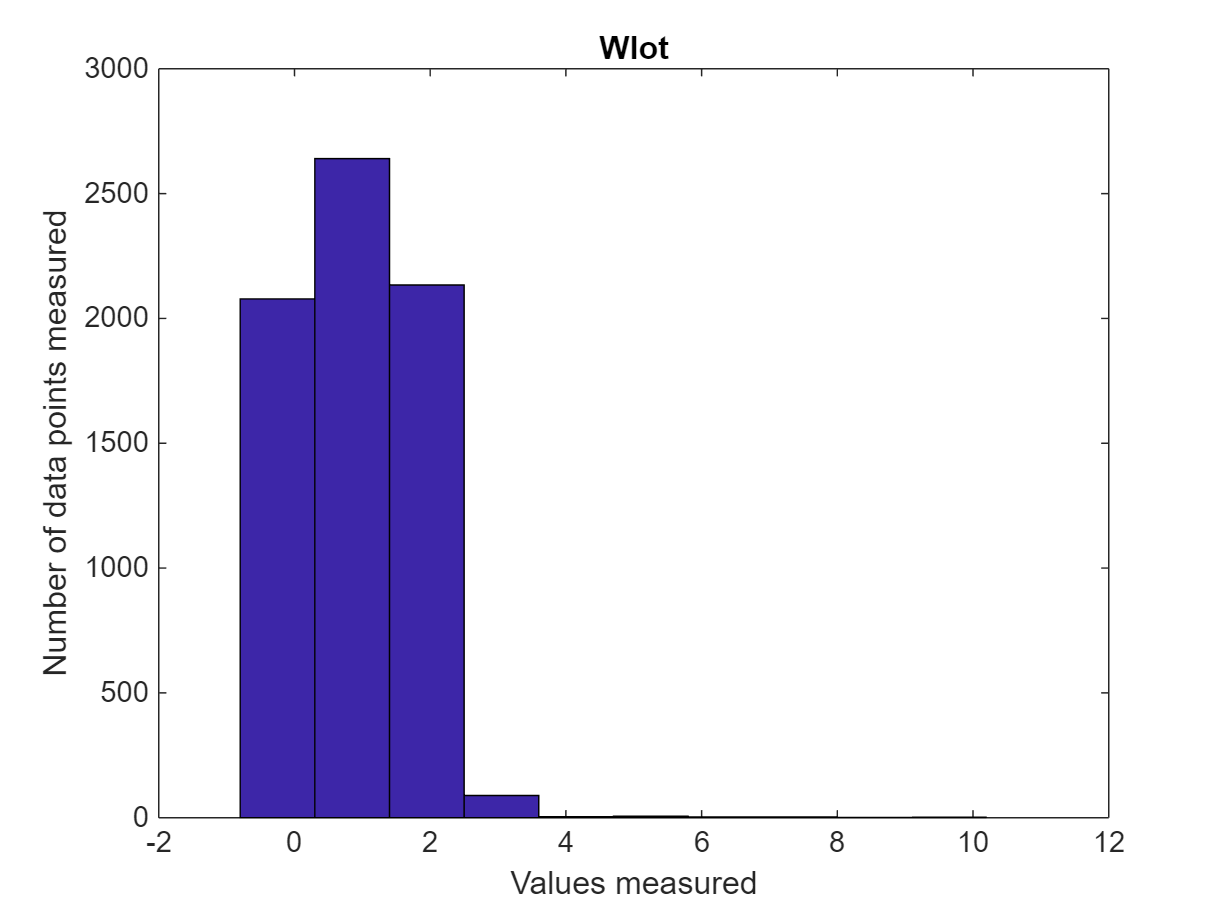

hist(X(4,:))
title('Wlot')
xlabel('Values measured')
ylabel('Number of data points measured')

test=InterpolateData(X(4,:),[0.005 0.15],t_all)

test =    -0.2000   -0.2000         0    0.2000    0.4000    0.7000    0.9000    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    0.2000    2.1000    0.2000    1.7000    1.3000    1.0500    0.8000    0.5000    0.2000         0   -0.2000   -0.3000   -0.2000         0    0.4000    0.6000    0.8000    0.9500    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    0.2000    2.1000    2.1000    1.8000    1.5000    1.1000    0.9000    0.6000    0.3000         0   -0.2000


test2=InterpolateData(test,[0.19 0.21],t_all)

test2 =    -0.2000   -0.2000         0    0.2000    0.4000    0.7000    0.9000    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    1.9000    1.7000    1.3000    1.0500    0.8000    0.5000    0.2500         0   -0.2000   -0.3000   -0.2000         0    0.4000    0.6000    0.8000    0.9500    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.1000    1.8000    1.5000    1.1000    0.9000    0.6000    0.3000         0   -0.2000


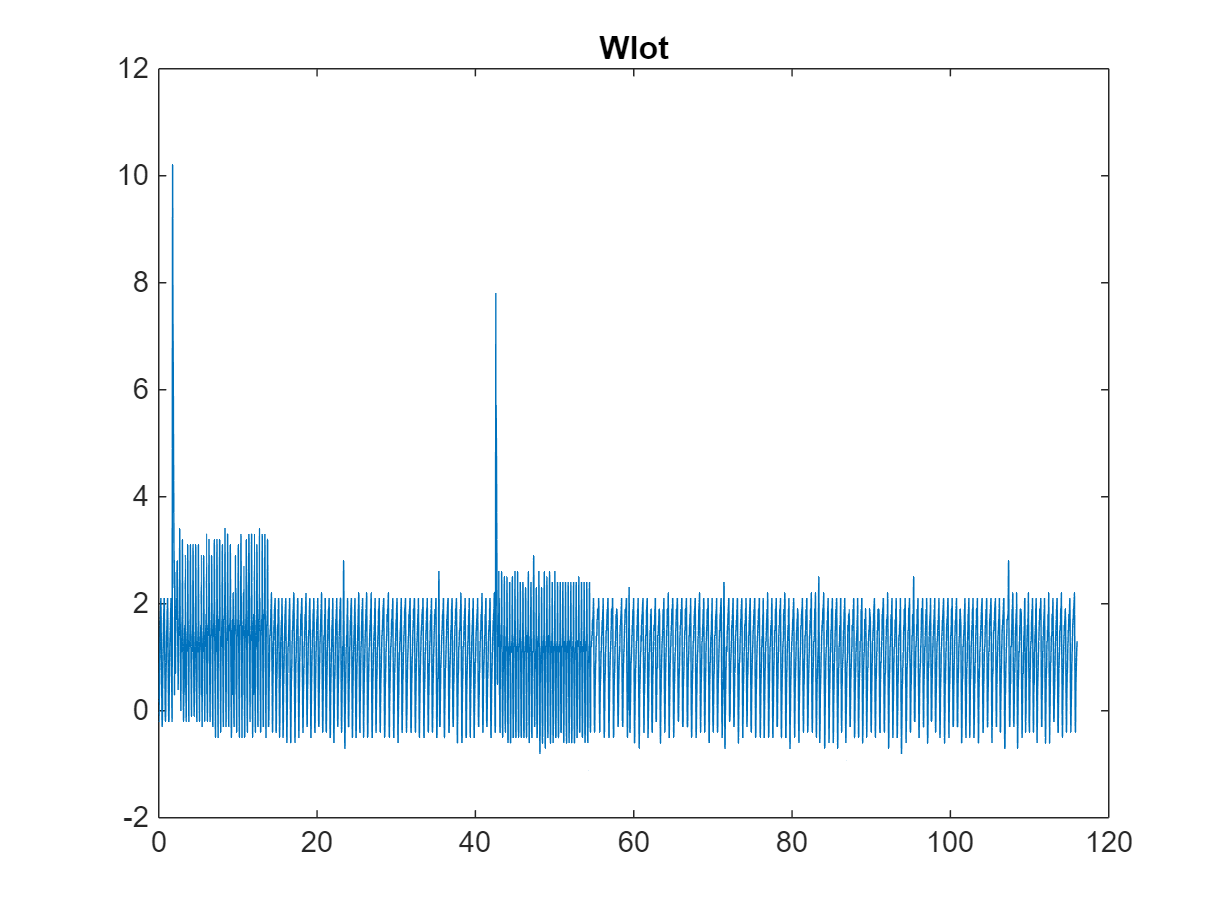

plot(t/(60*60),test2)
title('Wlot')

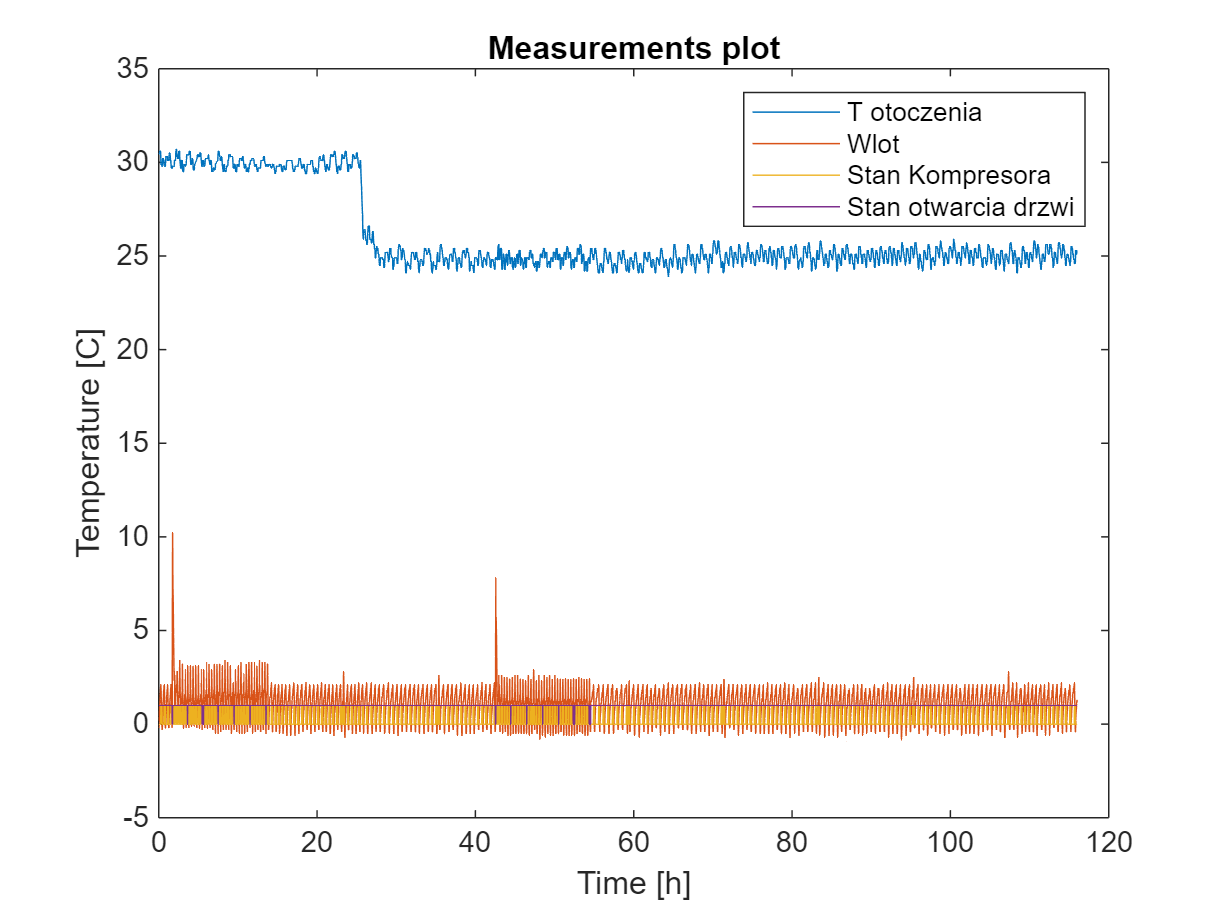

X_filtered=[InterpolateData(X(3,:),[2,3.5],t_all);test2];

plot(t/(60*60),X_filtered(1,:))
hold on
plot(t/(60*60),X_filtered(2,:))
plot(t/(60*60),X(1,:));
plot(t/(60*60),X(2,:));hold off
title('Measurements plot')
xlabel('Time [h]')
ylabel('Temperature [C]')
legend('T otoczenia','Wlot','Stan Kompresora','Stan otwarcia drzwi')

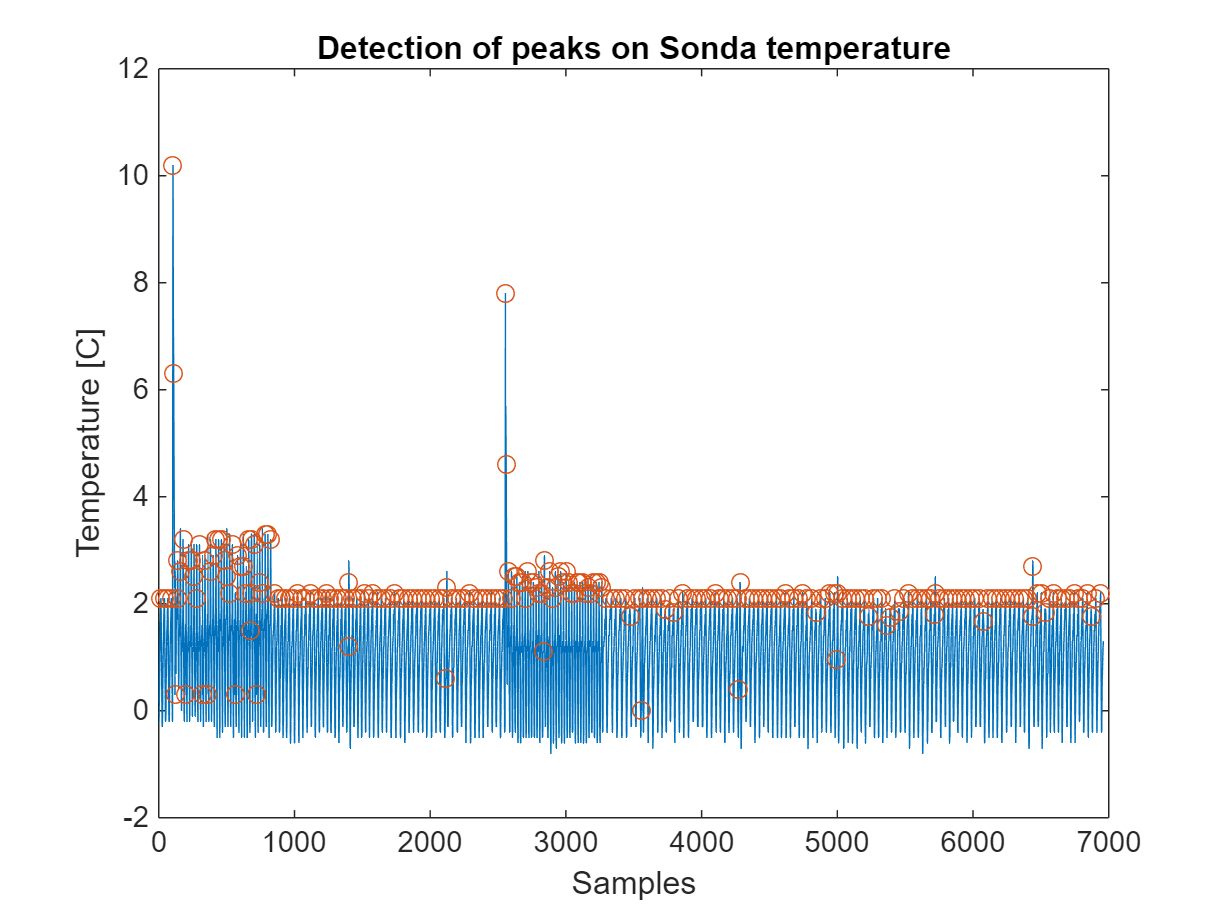

locs=compressorCycles(X(1,:));
x = FeatureExtract(X_filtered(2,:),locs);
plot((X_filtered(2,:)));hold on
plot(locs,(X_filtered(2,locs)),'o');hold off
title('Detection of peaks on Sonda temperature')
xlabel('Samples')
ylabel('Temperature [C]')

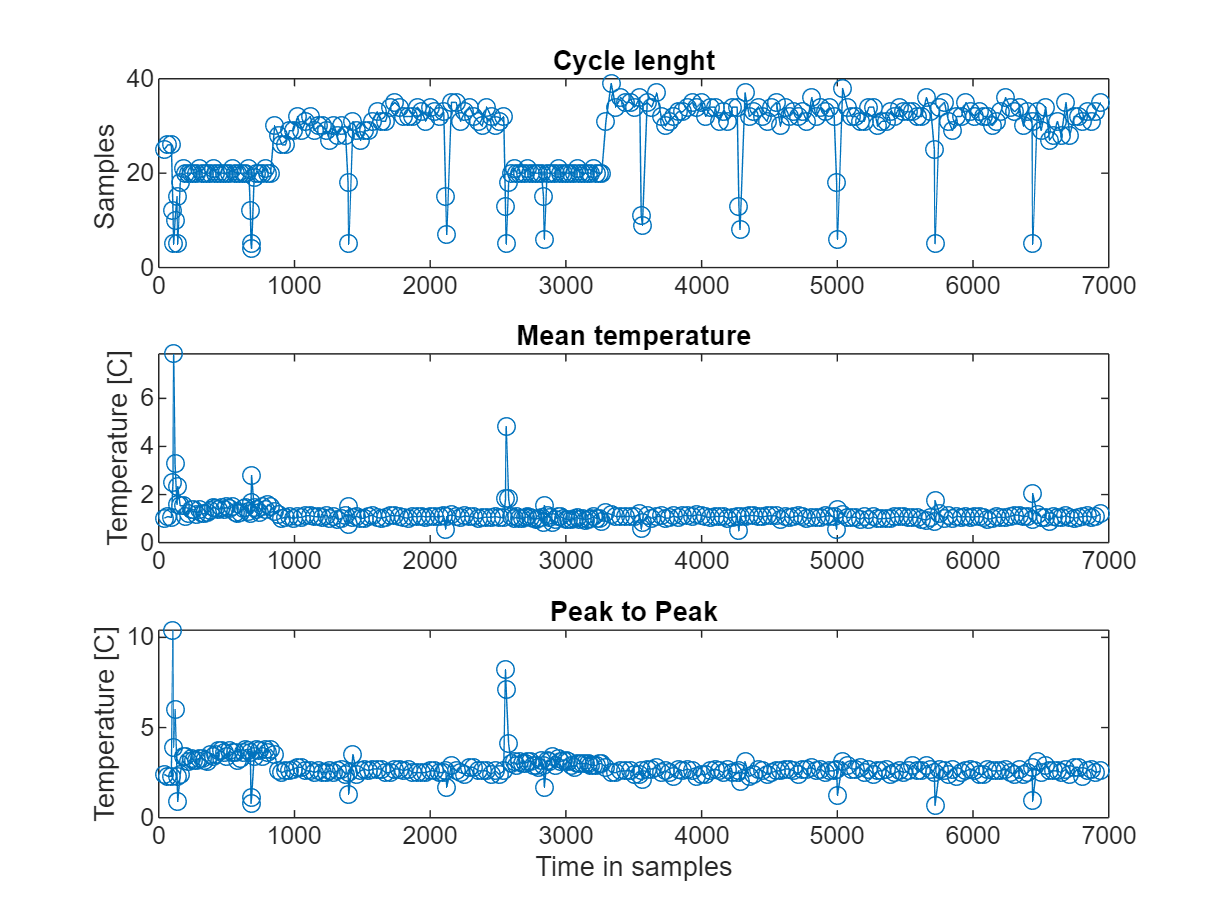

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);
figure 
subplot(311)
plot(locs,f1,'o-')
title('Cycle lenght')
ylabel('Samples ')
subplot(312)
plot(locs,x(3,:),'o-')
title('Mean temperature')
ylabel('Temperature [C]')
subplot(313)
plot(locs,x(1,:)-x(2,:),'o-')
title('Peak to Peak')
xlabel('Time in samples')
ylabel('Temperature [C]')

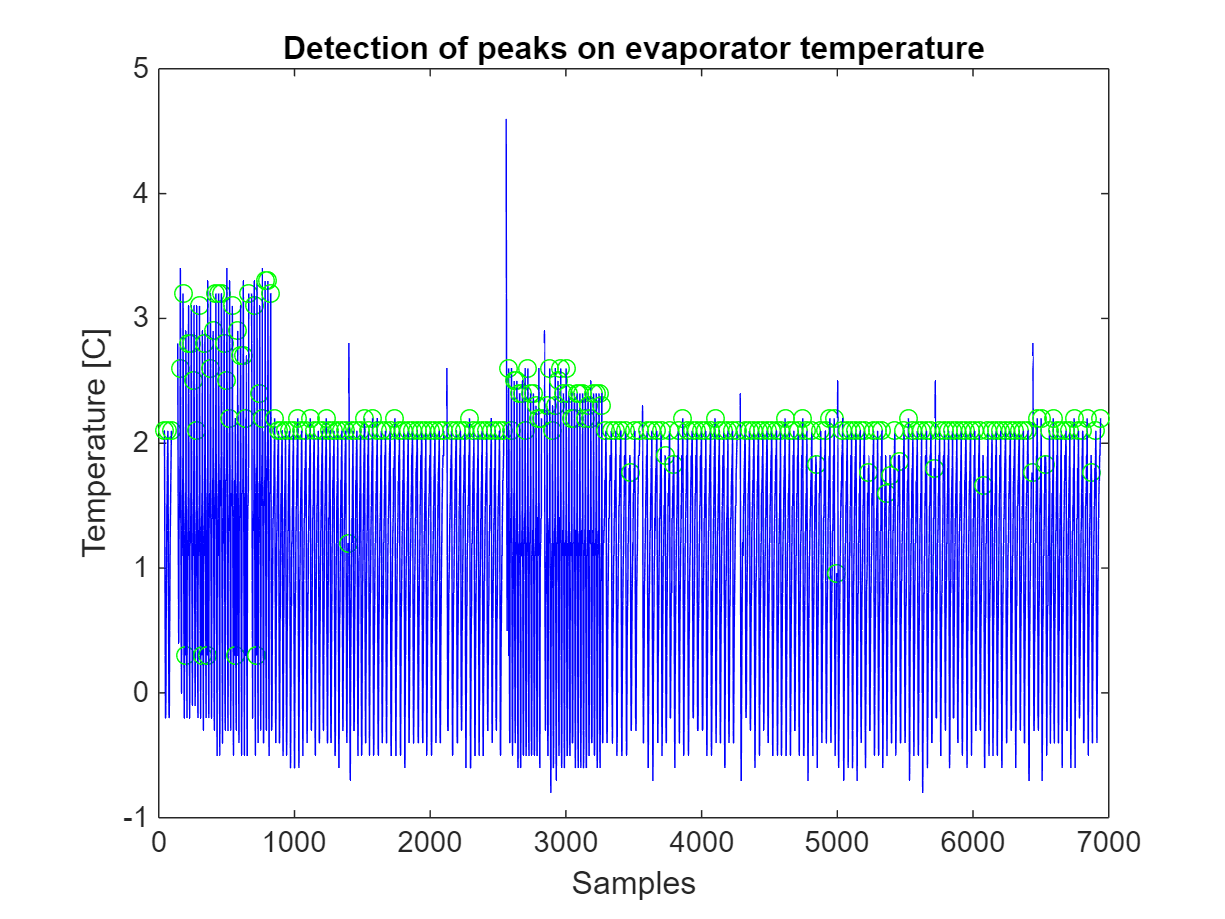

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(f1);
% TF = isoutlier(fridge_air_temp_p2p);

plot(locs(1),(X_filtered(2,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X_filtered(2,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X_filtered(2,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

Analysis of p2p suggest that the period of experiment was between sample 140 (pos indexContainer{2}(1)) and 824(pos indexContainer{3}(149))

Second period of experiment was: 2560 (pos indexContainer{6}(1)) and 3264 (pos indexContainer{7}(446))

usableDataIndex{1}=indexContainer{1};
usableDataIndex{2}=indexContainer{3}(1,149:end);
usableDataIndex{3}=indexContainer{4};
usableDataIndex{4}=indexContainer{5};
usableDataIndex{5}=indexContainer{7}(446:end);
for i=6:10
usableDataIndex{i}=indexContainer{i+2};
end

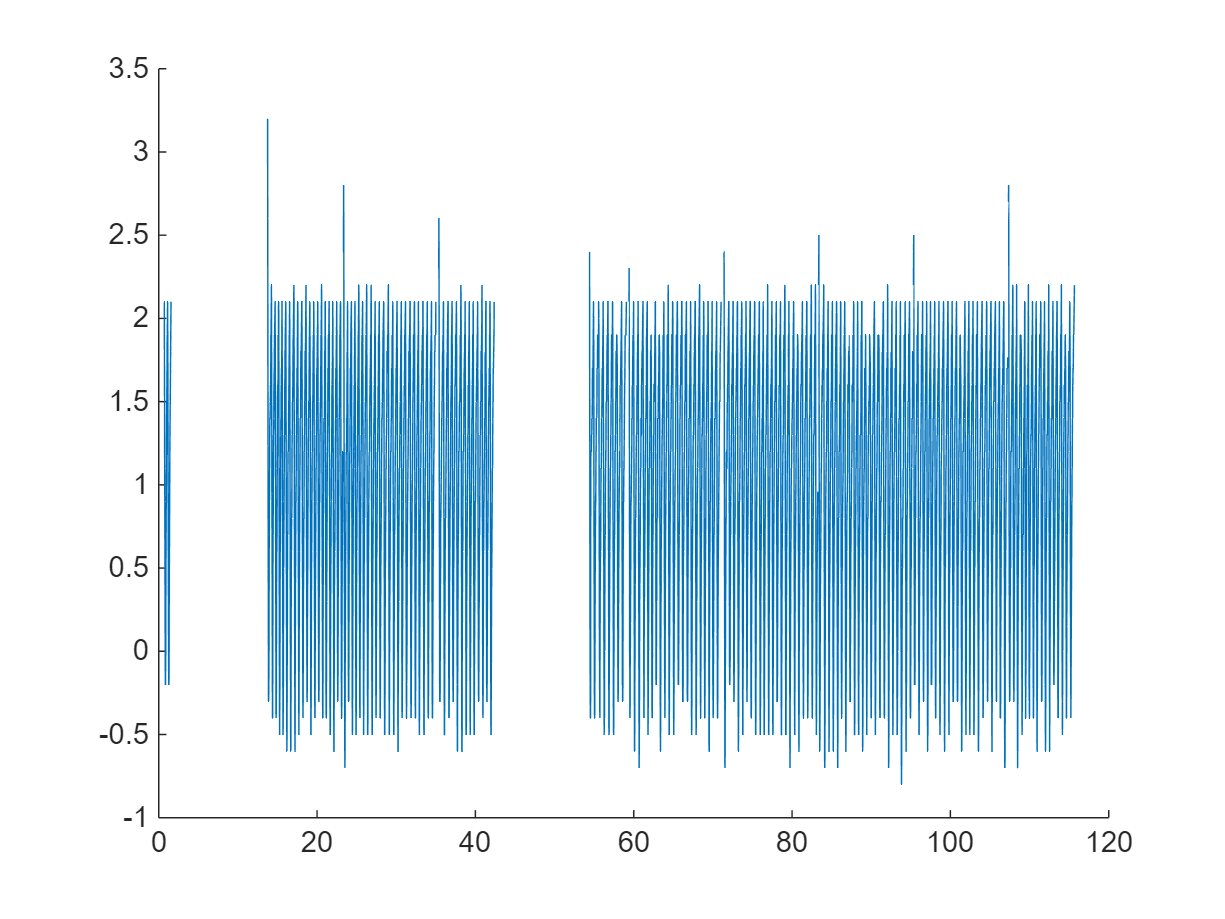

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(2,usableDataIndex{i}),'Color','#0072BD')
end
hold off

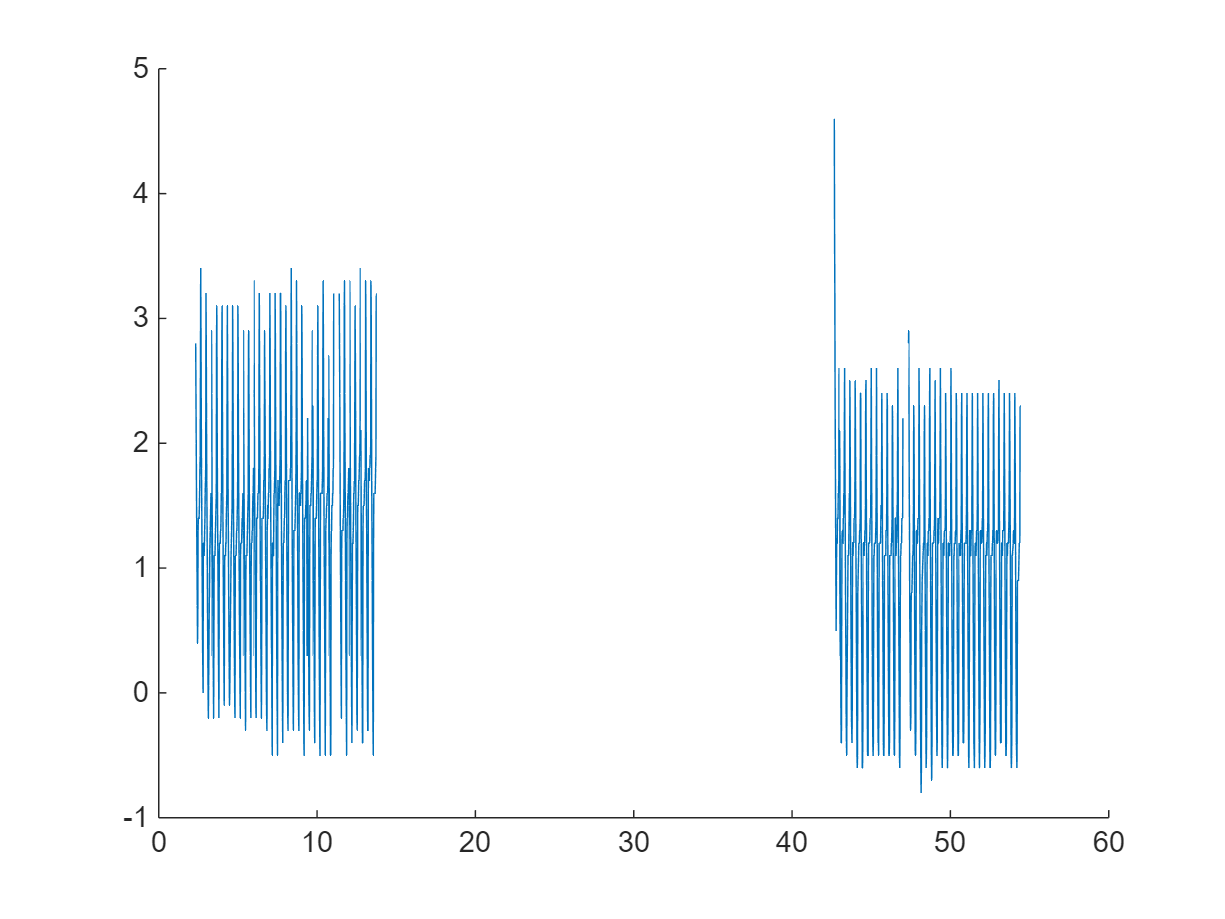


stat2ind={indexContainer{2};indexContainer{3}(1:148);indexContainer{6};indexContainer{7}(1:445)};

figure
hold on
for i = 1:length(stat2ind)
    plot(t(stat2ind{i})/(60*60),X_filtered(2,stat2ind{i}),'Color','#0072BD')
end
hold off

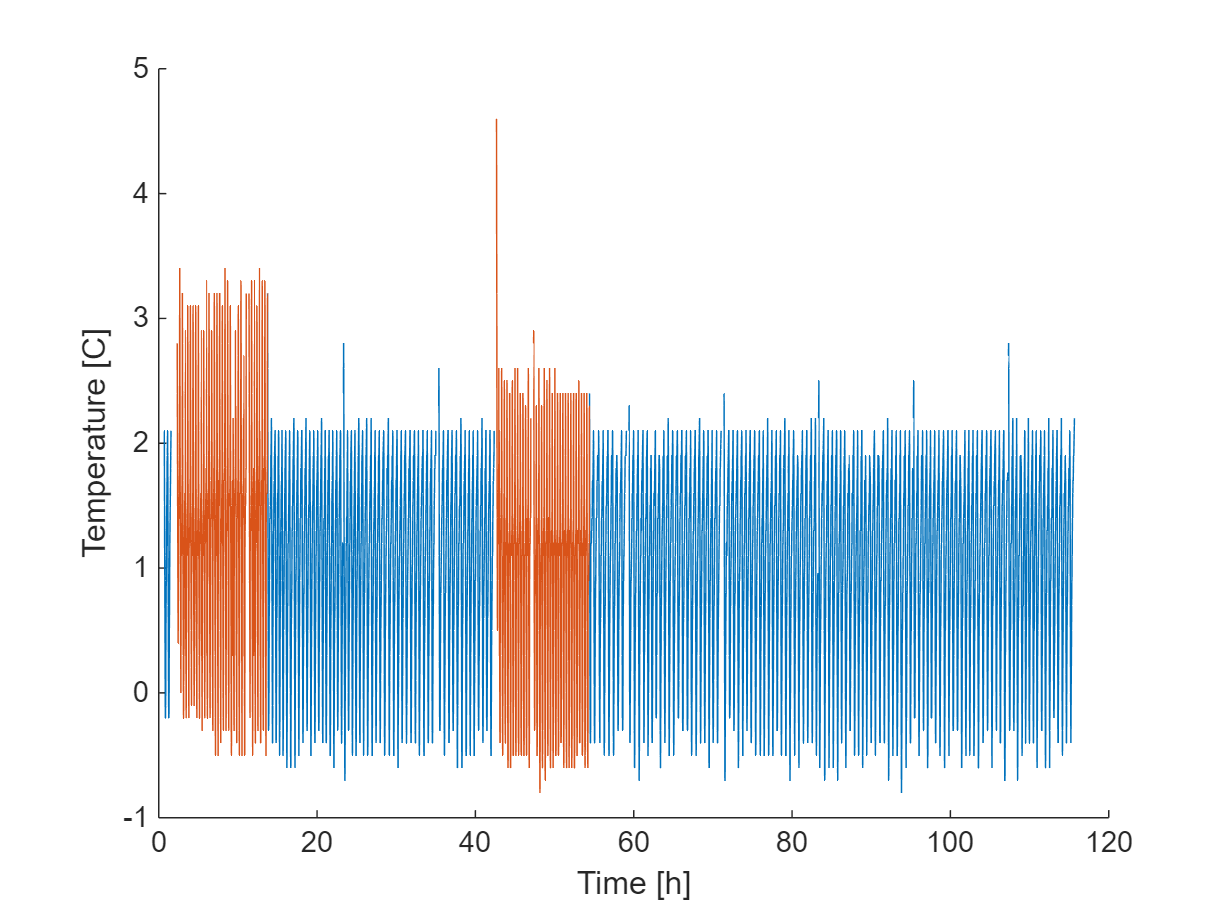

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X_filtered(2,usableDataIndex{i}),'Color','#0072BD')
end
for i = 1:length(stat2ind)
    plot(t(stat2ind{i})/(60*60),X_filtered(2,stat2ind{i}),'Color','#D95319')
end

hold off
xlabel('Time [h]')
ylabel('Temperature [C]')